## **Prerequisites**

clear 
clc
% Add YALMIP to local path
% addpath(genpath("C:\Users\amato\OneDrive\Documenten\TU\MSC S&C\Year 1\Q3 23-24\MPC"))
addpath(genpath("C:\Users\tommo\Documents\TUDelft\Msc_Systems_and_Control\MPC\YALMIP-master"))

## **Continuous Time State Space**

*Linearized continuous time system dynamics derived from Bencatel et al.*

% Linearized Continuous Time State Space Matrices
A = [-0.135 -4.905 0.125 0.176 4.902;
      0.180 -7.132 -1.419 -0.075 -7.132;
      0 -0.768 -1.315 0.014 -0.768;
      0 10.85 0 0 0;
      0 0 1 0 0]; 
B = [-4.078 4.555 -1.254 0 0;
     -0.226 2.566 2.378 0 0]';
C = [0 0 0 1 0;
     0 0 0 0 1];
D = [];

## **Discretizing the System using ZOH and Sampling Period h (without disturbance)**

*Creating a discrete time version of the state space sampled at interval h using zero order hold.*

% Choose Sampling Period (Obtained from previous analysis)
h = 0.5; %in seconds

% Create DT SS
Psi=expm(A*h);
fun=@(t)expm(A.*t);
Gamma=integral(fun,0,h,'ArrayValued',1)*B;

% Verify Controllability & Observability
CO_dt = ctrb(Psi,Gamma); % Controllability Matrix
OBS_dt = obsv(Psi,C); % Observability matrix
if rank(CO_dt) == size(Psi,1) && min(svd(CO_dt)) >= 0.001
    fprintf("DT System Controllable :)")
else
    warning("DT System not Controllable :(")
end

DT System Controllable :)

if rank(OBS_dt) == size(Psi,1) && min(svd(OBS_dt)) >= 0.001
    fprintf("DT System Observable :)")
else
    warning("DT System not Observable :(")
end

DT System Observable :)


% Definition of DT System Matrices
AC45.A = Psi;
AC45.B = Gamma;
AC45.C = C;
AC45.D = D;

% Definition of System Dimensions
dim.nx = size(AC45.A, 1);    % state dimension
dim.ny = size(AC45.C, 1);    % output dimension
dim.nu = size(AC45.B, 2);    % input dimension
dim.N = 20;                  % horizon
dim.e = 2;

## Reference Tracking MPC Controller

*We implement a reference tracking MPC Controller and iterate over multiple time horizons to obtain a desirable N.*

## **Input and State Weights**

*Defining input & state weights. Use these weights to construct the cost function.*

% Define state and input penalties
weight.Q = diag([0.1 10 1 100 1]); % weight on states
weight.R = diag([1 0.1]); % weight on input

% Solve DARE
[P,K,L] = idare(Psi,Gamma,weight.Q,weight.R); 
K = -K; weight.P=P;

## Constraints

*Define inupt and state constraints.*

% Input Constraints
F1 = [0 1 0 0 -1; 
      0 -1 0 0 1; 
      0 0 0 0 0; 
      0 0 0 0 0];
E1 = [1 0;-1 0;0 1;0 -1];
e1 = [12;12;5;5];

% Tight State Constraints
F2 = [0 0 0 1 0;
      0 0 0 -1 0];
e2 = [0.5; 0.315];

% Loose State Constraints
F3 = [0 0 0 0 1;  % theta (pitch angle)
      0 0 0 0 -1;
      1 0 0 0 0;  % V_H (Hydrodynamic speed)
      -1 0 0 0 0; 
      0 1 0 0 0;  % gamma (flight path angle)
      0 -1 0 0 0;
      0 0 1 0 0;  % q (angular velocity)
      0 0 -1 0 0];
e3 = [20; 20; 
      5; 5;
      20;20; 
      20; 20];

% Compact notation of constraints
F =[F1; F2; F3]; E =[E1; zeros(2,2); zeros(8,2)];
e = [e1;e2;e3];

## Optimal Prediction Horizon 

*Define the optimal control problem for different values of N*

% Request simulation time
prompt = "Input simulation time: ";
T_sim = input(prompt)

T_sim = 100


% Number of Experiments
dim.exp = 4;
Nexp=[10 12 15 20];

% Initialize Results
y_ref=[0.3;0]; % Output target
x=zeros(dim.nx*dim.exp,T_sim+1); x(:,1)=zeros(dim.nx*dim.exp,1); % Initial condition
u_rec = zeros(dim.nu*dim.exp,T_sim);
y=zeros(dim.ny*dim.exp,T_sim+1);

% Create different MPC Controller for each N
for exp = 1:dim.exp
    dim.N=Nexp(exp);
    id_y=2:2:dim.exp*dim.ny;
    id_u=2:2:dim.exp*dim.nu;

    % Prediction matrix from initial state
    T = zeros(dim.nx*(dim.N+1),dim.nx);
    for k = 0:dim.N
        T(k*dim.nx+1:(k+1)*dim.nx,:) = AC45.A^k;
    end
    predmod.T = T;

    % Prediction matrix from input
    S = zeros(dim.nx*(dim.N+1),dim.nu*(dim.N));
    for k = 1:dim.N
        for i = 0:k-1
            S(k*dim.nx+1:(k+1)*dim.nx,i*dim.nu+1:(i+1)*dim.nu) = AC45.A^(k-1-i)*AC45.B;
        end
    end
    predmod.S = S;
    
    % Terminal Set, last lines of S and T (i.e., x(N))
    constraints.Ae=predmod.S(end-dim.nx+1:end,:); 
    constraints.be=predmod.T(end-dim.nx+1:end,:);

    % Concatenate Constraint LMIs
    F_diag = kron(eye(dim.N),F); %block diagonal F matrix
    E_diag = kron(eye(dim.N),E); %block diagonal E matrix
    e_concat = kron(ones(dim.N,1),e);

    % Generate Cost Function
    Qbar = blkdiag(kron(eye(dim.N),weight.Q),weight.P); 
    Rbar=kron(eye(dim.N),weight.R); 
    H=S'*Qbar*S+Rbar;
    mu_x0=S'*Qbar*T;
    mu_xref=-S'*Qbar*kron(ones(dim.N+1,1),eye(dim.nx));
    mu_uref=-Rbar*kron(ones(dim.N,1),eye(dim.nu));
    mu=[mu_x0 mu_xref mu_uref];
    
    % Check Terminal Set
    % (Orthogonally) Diagonalize P
    [V_p,D_p] = eig(P); % Check for x'TPx instead of 1/2x'TPx, numerically more reliable
    disp('Check if product is identity:')
    V_p'*V_p % Visually check that V_p is an orthogonal basis, i.e. product is identity
    
    c = 2; %Level curve of your choice, iterate
    
    % Define hyperrhombus vertices approximating ellipsoid
    rh_vert = 2*(inv(D_p)*(c*ones(size(D_p,1),1))); % Construct column vector of vertices
    
    % Transform coordinates for both signs
    rh_vert_tf = V_p*rh_vert;
    
    % Check constraints, per region
    if F*rh_vert_tf + E*(K*rh_vert_tf) <= e
        fprintf('Constraints are satisfied')
    else
        warning('Constraints are not satisfied')
    end
    
    % Start opt. time cumulative for each experiment
    sol_data.yalmiptime=0; sol_data.solvertime=0;

    % Begin receding horizon implementation
    for k = 1:T_sim

        % Store results in organized fashion
        sel_index=linspace(1,dim.nx,dim.nx)+(exp-1)*dim.nx*ones(dim.nx,1);
        x_0=x(sel_index(1):sel_index(end),k); 

        % Define Optimization Variables
        x_r = sdpvar(dim.nx,1); u_r = sdpvar(dim.nu,1);

        % Define Constraints
        ots.cons_mat = [eye(dim.nx) - AC45.A, -AC45.B; AC45.C, zeros(dim.ny,dim.nu)]; 
        ots.cons_ref = [ots.cons_mat*[x_r;u_r]==[zeros(dim.nx,1);y_ref]]; % Steady State Constraint
        ots.cons_state = [F*x_r + E*u_r <= e];
        ots.cons_all = [ots.cons_ref; ots.cons_state];

        % Define Objective
        ots.obj = [norm(u_r)];

        % Solve OTS
        ops =  sdpsettings('verbose',0);                         
        sol_ots = optimize(ots.cons_all,ots.obj, ops);  

        % Analyze error flags
        if sol_ots.problem ~ 0
            warning('Something went wrong!');
            sol_ots.info
            yalmiperror(sol_ots.problem)
            warning('Loop Terminated!');
            break
        end

        % Extract values of minimizer: reference input and -state
        u_r=value(u_r); x_r=value(x_r);
        
        % Solve the Optimal Control Problem (with YALMIP)
        u_con = sdpvar(dim.nu*dim.N,1);                          % Define optimization variable
        x_N = constraints.Ae*u_con + constraints.be*x_0;         % Terminal State

        % Constraints: terminal set and general constraints
        constraints.terminal = [(x_N-x_r)'*P*(x_N-x_r) <= c];    
        constraints.state = [F_diag*T(dim.nx+1:end,:)*x_0 + (F_diag*S(dim.nx+1:end,:)+E_diag)*u_con <= e_concat];
        constraints.all = [constraints.terminal;constraints.state];

        % Objective Function
        Objective = 0.5*u_con'*H*u_con+(mu*[x_0; x_r; u_r])'*u_con; % Define objective function

        % Optimize
        ops =  sdpsettings('verbose',0,'cachesolvers',1,'saveduals',0);                        
        sol = optimize(constraints.all,Objective, ops);          % Solve the problem

        % Analyze error flags
        if sol.problem ~ 0
            warning('Something went wrong!');
            sol.info
            yalmiperror(sol.problem)
            warning('Loop Terminated!');
            break
        end

        % Save YALMIP and Solvertime
        sol_data.yalmiptime = sol_data.yalmiptime + sol.yalmiptime;
        sol_data.solvertime = sol_data.solvertime + sol.solvertime;

        % Extract solution
        u_con=value(u_con);                                       

        % Select the first input only
        u_rec(id_u(exp)-1:id_u(exp),k)=u_con(1:2);
        
        clear u_con u_r x_r
    
        % Compute the state/output evolution
        u=u_rec(id_u(exp)-1:id_u(exp),k);
        x(sel_index(1):sel_index(end),k+1)=AC45.A*x_0 + AC45.B*u;
        y(id_y(exp)-1:id_y(exp),k+1)=AC45.C*x(sel_index(1):sel_index(end),k+1);
    end
end

Check if product is identity:


ans =     1.0000    0.0000    0.0000   -0.0000    0.0000
    0.0000    1.0000   -0.0000    0.0000   -0.0000
    0.0000   -0.0000    1.0000    0.0000    0.0000
   -0.0000    0.0000    0.0000    1.0000   -0.0000
    0.0000   -0.0000    0.0000   -0.0000    1.0000


Constraints are satisfied

Check if product is identity:


ans =     1.0000    0.0000    0.0000   -0.0000    0.0000
    0.0000    1.0000   -0.0000    0.0000   -0.0000
    0.0000   -0.0000    1.0000    0.0000    0.0000
   -0.0000    0.0000    0.0000    1.0000   -0.0000
    0.0000   -0.0000    0.0000   -0.0000    1.0000


Constraints are satisfied

Check if product is identity:


ans =     1.0000    0.0000    0.0000   -0.0000    0.0000
    0.0000    1.0000   -0.0000    0.0000   -0.0000
    0.0000   -0.0000    1.0000    0.0000    0.0000
   -0.0000    0.0000    0.0000    1.0000   -0.0000
    0.0000   -0.0000    0.0000   -0.0000    1.0000


Constraints are satisfied

Check if product is identity:


ans =     1.0000    0.0000    0.0000   -0.0000    0.0000
    0.0000    1.0000   -0.0000    0.0000   -0.0000
    0.0000   -0.0000    1.0000    0.0000    0.0000
   -0.0000    0.0000    0.0000    1.0000   -0.0000
    0.0000   -0.0000    0.0000   -0.0000    1.0000


Constraints are satisfied

    
    disp('Average Yalmip and Solver time')

Average Yalmip and Solver time


    sol_data.yalmiptime/T_sim

ans = 0.3130

    sol_data.solvertime/T_sim

ans = 0.2688

## **Plotting Results**

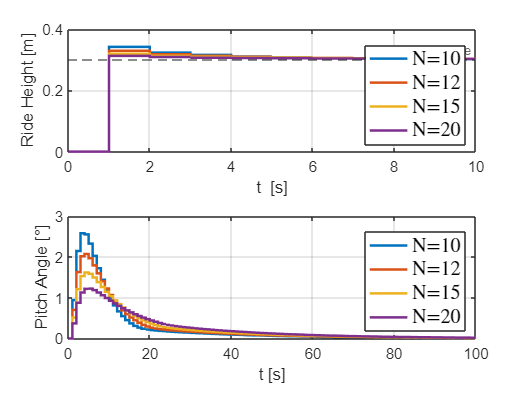

% Plot States

%Subplot 1 for z
figure,
% Subplot 1 for 'Height [m]' corresponding to 'z'
subplot(2,1,1); 
zplot=[];
for j = 1:2:dim.exp*dim.ny
    zplot=[zplot y(j,:)'];
end
stairs(0:T_sim, zplot,'LineWidth',2);
ylabel('Ride Height [m]');
xlabel('t  [s]');
yline(0.3,'--','Reference');
ylim([0 0.4]);xlim([0 10]);
lgd = legend({'N=10','N=12','N=15','N=20'},'Interpreter','latex');
lgd.Location = 'southeast';
lgd.FontSize = 16;
grid on;
set(gca, 'FontSize', 12);

% Subplot 2 for 'Pitch Angle [degrees]' corresponding to '\theta'
subplot(2,1,2); 
thplot=[];
for j = 2:2:dim.exp*dim.ny
    thplot=[thplot y(j,:)'];
end
stairs(0:T_sim, thplot,'LineWidth',2);
ylabel('Pitch Angle [°]');
xlabel('t [s]');
lgd = legend({'N=10','N=12','N=15','N=20'},'Interpreter','latex');
lgd.Location = 'southeast';
lgd.FontSize = 16;
grid on;
grid on;
set(gca, 'FontSize', 12);

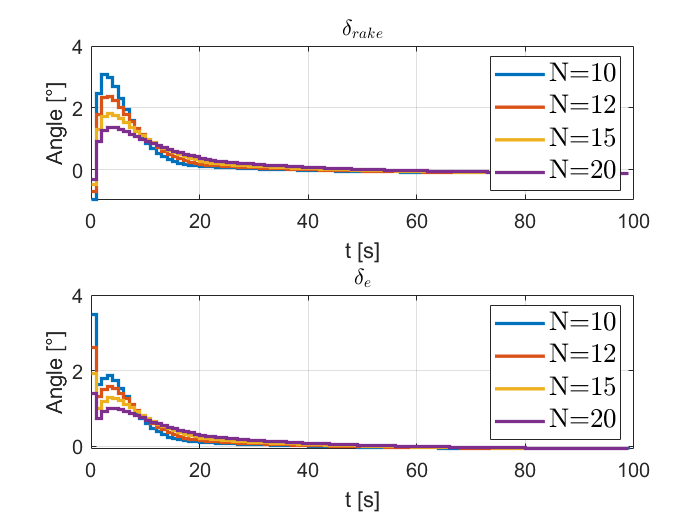


% Plot Inputs

figure,
% Subplot 1 for Daggerboard Rake corresponding to 'u1'
subplot(2,1,1); 
u1plot=[];
for j = 1:2:dim.exp*dim.ny
    u1plot=[u1plot u_rec(j,:)'];
end
stairs(0:T_sim-1, u1plot,'LineWidth',2);
ylabel('Angle [°]');
xlabel('t [s]');
lgd = legend({'N=10','N=12','N=15','N=20'},'Interpreter','latex');
lgd.Location = 'southeast';
lgd.FontSize = 16;
title({'$\delta_{rake}$'},'Interpreter','latex');
grid on;
set(gca, 'FontSize', 12);

% Subplot 2 for Rudder Rake corresponding to 'u2'
subplot(2,1,2); 
u2plot=[];
for j = 2:2:dim.exp*dim.ny
    u2plot=[u2plot u_rec(j,:)'];
end
stairs(0:T_sim-1, u2plot,'LineWidth',2);
ylabel('Angle [°]');
xlabel('t [s]');
lgd = legend({'N=10','N=12','N=15','N=20'},'Interpreter','latex');
lgd.Location = 'southeast';
lgd.FontSize = 16;
title({'$\delta_{e}$'},'Interpreter','latex');
grid on;
set(gca, 'FontSize', 12);